# MATLAB Advanced Signal Processing

**Computer Applications in Transportation (2101553)**

**Siwarak Unsiwilai, Ph.D.**

Email: [siwarak.u@chula.ac.th](mailto:siwarak.u@chula.ac.th) Office: CE Building, Room 534

## Initial Step: Check for Required Toolbox

This ensures students have the necessary MATLAB tools before starting the analysis.

%% Initial Step: Check for Required Toolbox
% This lab requires the Signal Processing Toolbox.

% Clear workspace for a fresh start
clear all;
clc;
close all;

% --- Toolbox Check ---
% Use 'ver' to get version info for all toolboxes
toolbox_info = ver;

% Check if 'Image Processing Toolbox' is in the list of names
is_installed = any(strcmp({toolbox_info.Name}, 'Signal Processing Toolbox'));

% *** CORRECTED LOGIC ***
if is_installed
    disp('Success: Image Processing Toolbox is installed.');
    disp('You can run the rest of the script.');
else
    % If not installed, stop the script and show an error
    error(['Signal Processing Toolbox not found. Please install it to continue.' ...
           '\n\nTo install:' ...
           '\n1. Go to the Home tab' ...
           '\n2. Click Add-Ons > Manage Add-Ons' ...
           '\n3. Search for "Signal Processing Toolbox" and install it.' ...
           '\n4. Restart MATLAB and run this script again.']);
end

Success: Image Processing Toolbox is installed.


You can run the rest of the script.


## **Part 1: Signal Setup, Problem Visualization, and STFT Initial Analysis**

### **1.1 Generating the Non-Stationary Signal (Including Noise for later steps)**

We generate the signal with the localized defect, including significant **White Noise** for the filtering exercise later.

% Clear workspace, command window, and all figures
clear; clc; close all;

% --- Fundamental Parameters ---
Fs = 1000;              % Sampling frequency (Hz)
L = 1000;               % Signal Length (1 second)
T = 1/Fs;
t = (0:L-1)*T;          % Time vector

% --- Signal Components ---
f1 = 50;                % Continuous base frequency
f_event = 250;          % Localized impact frequency

% 1. Clean Signal: 50 Hz base + 250 Hz event (0.4s to 0.6s)
t_start = 0.4;
t_end = 0.6;
event_zone = (t >= t_start) & (t <= t_end);
y_clean = 0.7 * cos(2*pi*f1*t); 
y_clean(event_zone) = y_clean(event_zone) + 1.2 * cos(2*pi*f_event*t(event_zone));

% 2. Add White Noise
noise_power = 0.5 * randn(size(t)); 
y_noisy = y_clean + noise_power;

### **1.2 Visualizing the Time Domain and Standard FFT (The Problem)**

This stage visualizes the noisy signal and shows the fundamental limitation of the FFT

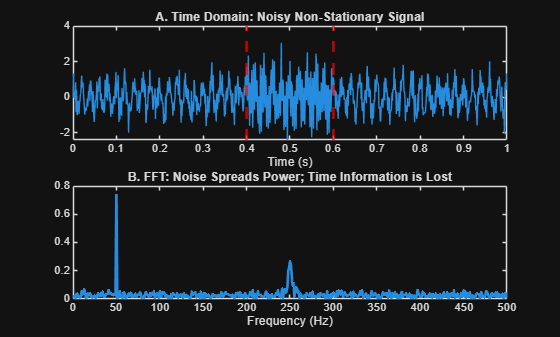

% --- STAGE 1.2: VISUALIZE THE PROBLEM ---

% 1. Calculate the standard FFT on the NOISY signal
Y_fft_ns = fft(y_noisy);
P2_ns = abs(Y_fft_ns / L);
P1_ns = P2_ns(1:L/2+1);
P1_ns(2:end-1) = 2 * P1_ns(2:end-1);
f = Fs * (0:(L/2)) / L;

figure;
subplot(2, 1, 1);
plot(t, y_noisy);
xline([t_start, t_end], 'r--', 'LineWidth', 2);
title('A. Time Domain: Noisy Non-Stationary Signal');
xlabel('Time (s)');

subplot(2, 1, 2);
plot(f, P1_ns, 'LineWidth', 2);
title('B. FFT: Noise Spreads Power; Time Information is Lost');
xlabel('Frequency (Hz)');
xlim([0 Fs/2]);


disp('Review: The FFT shows WHAT frequencies are present (50 Hz, 250 Hz, and widespread noise), but it fails to tell us WHEN the 250 Hz event occurred.');

Review: The FFT shows WHAT frequencies are present (50 Hz, 250 Hz, and widespread noise), but it fails to tell us WHEN the 250 Hz event occurred.


## **Part 2: The Short-Time Fourier Transform (STFT) and Denoising**

We introduce the solution (STFT) but quickly show that filtering is essential for accurate results.

### **2.1 **Initial Spectrogram Analysis (The Noise Problem)

We run the STFT initially on the y_noisy signal.

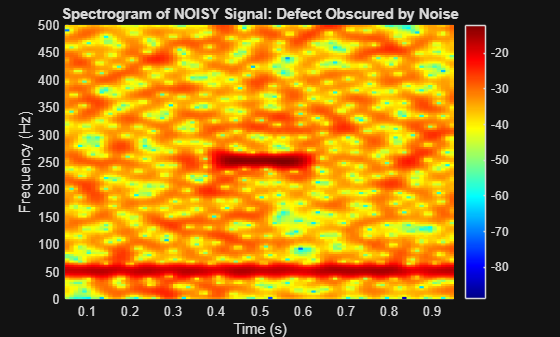

%% 2.1 STFT on Noisy Signal (Initial Look)

% STFT Parameters (Initial Choice)
window_length = 100;    
overlap = 90;          

% Calculate STFT on the NOISY signal
[~, F, T_stft, P_noisy] = spectrogram(y_noisy, window_length, overlap, [], Fs);

figure;
surf(T_stft, F, 10*log10(P_noisy), 'edgecolor', 'none'); 
axis tight;
view(0, 90); 
colormap(jet);
colorbar;
title('Spectrogram of NOISY Signal: Defect Obscured by Noise');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([0 Fs/2]);


disp('Observation: The STFT finds the time, but the noise (blue/green haze) makes the 250 Hz defect very hard to isolate visually. This is why we must filter.');

Observation: The STFT finds the time, but the noise (blue/green haze) makes the 250 Hz defect very hard to isolate visually. This is why we must filter.


### **2.2 Designing and Applying the Bandpass Filter**

We design a digital Bandpass Filter to keep our signal frequencies (10 Hz to 300 Hz) and reject high-frequency noise.

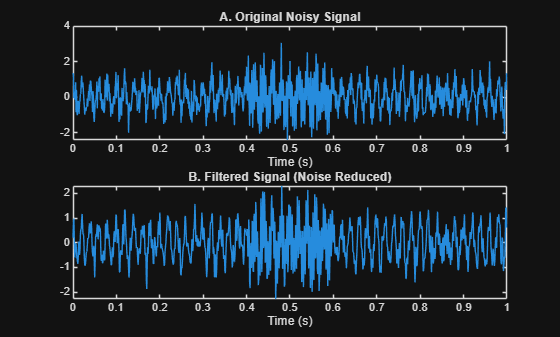

%% 2.2 Designing and Applying the Bandpass Filter

% --- FILTER DESIGN ---
f_low_cutoff = 10;     
f_high_cutoff = 300;   

% Design a Bandpass Filter (4th order Butterworth filter)
filter_order = 4;
[b, a] = butter(filter_order, [f_low_cutoff, f_high_cutoff] / (Fs/2), 'bandpass');

% Apply the filter to the noisy signal
y_filtered = filter(b, a, y_noisy);

figure;
subplot(2, 1, 1);
plot(t, y_noisy);
title('A. Original Noisy Signal');
xlabel('Time (s)');

subplot(2, 1, 2);
plot(t, y_filtered);
title('B. Filtered Signal (Noise Reduced)');
xlabel('Time (s)');

### **2.3 Final Spectrogram on the Cleaned Signal**

This is the final, clean, and unambiguous result for defect detection.

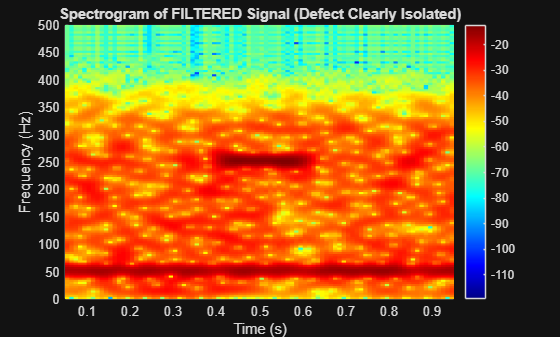

%% 2.3 Final Spectrogram on the Cleaned Signal

% Re-calculate STFT using the same parameters, but on the filtered data
[~, F_clean, T_clean, P_clean] = spectrogram(y_filtered, window_length, overlap, [], Fs);

figure;
surf(T_clean, F_clean, 10*log10(P_clean), 'edgecolor', 'none'); 
axis tight;
view(0, 90); 
colormap(jet);
colorbar;
title('Spectrogram of FILTERED Signal (Defect Clearly Isolated)');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([0 Fs/2]);


disp('Final Analysis: The filtering successfully removed noise power, and the 250 Hz localized defect is clearly isolated from 0.4s to 0.6s.');

Final Analysis: The filtering successfully removed noise power, and the 250 Hz localized defect is clearly isolated from 0.4s to 0.6s.


## Part 3: STFT Parameter Trade-Off (Final Exam Concept)

This section demonstrates the core engineering challenge: the fundamental compromise between Time Resolution and Frequency resolution based on the window length.

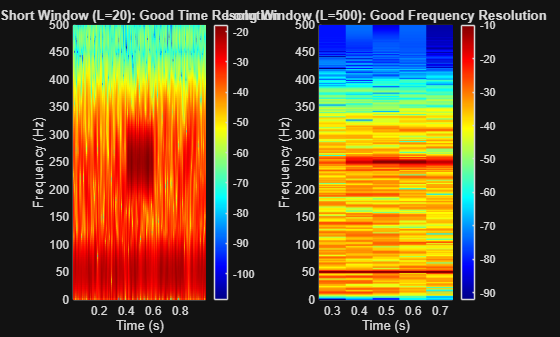

%% Part 3: STFT Parameter Trade-Off

% --- STAGE 3.1: WINDOW TRADE-OFF (Demonstration) ---

% Define window lengths that represent the extremes
short_window = 20;  % Excellent Time Resolution (Poor Frequency Resolution)
long_window = 500;  % Poor Time Resolution (Excellent Frequency Resolution)

% 1. Short Window Spectrogram 
[~, F_short, T_short, P_short] = spectrogram(y_filtered, short_window, 15, [], Fs);

% 2. Long Window Spectrogram
[~, F_long, T_long, P_long] = spectrogram(y_filtered, long_window, 400, [], Fs);


figure;
subplot(1, 2, 1);
surf(T_short, F_short, 10*log10(P_short), 'edgecolor', 'none'); 
axis tight; view(0, 90); colorbar; colormap(jet);
title(['Short Window (L=', num2str(short_window), '): Good Time Resolution']);
xlabel('Time (s)'); ylabel('Frequency (Hz)'); ylim([0 Fs/2]);

subplot(1, 2, 2);
surf(T_long, F_long, 10*log10(P_long), 'edgecolor', 'none'); 
axis tight; view(0, 90); colorbar; colormap(jet);
title(['Long Window (L=', num2str(long_window), '): Good Frequency Resolution']);
xlabel('Time (s)'); ylabel('Frequency (Hz)'); ylim([0 Fs/2]);


disp('Engineering Conclusion: For the final exam, remember the trade-off: use a short window to pinpoint the time of impact, or a long window to precisely identify the defect frequency.');

Engineering Conclusion: For the final exam, remember the trade-off: use a short window to pinpoint the time of impact, or a long window to precisely identify the defect frequency.
